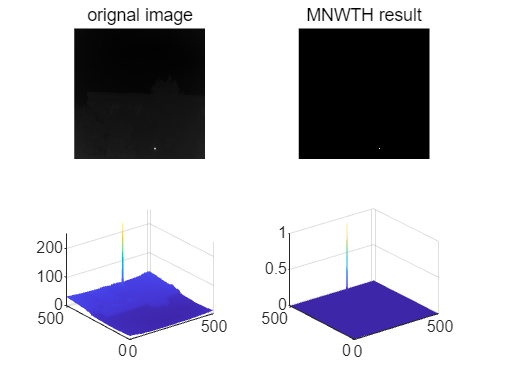

clc;clear;close all

img = imread('XDU147.png');
R_o = 9;
R_i = 4;
delta_B = newRingStrel(R_o, R_i);
B_b = ones(R_i);
img_MNWTH = MNWTH(img, delta_B, B_b);
subplot(221)
imshow(img);title('orignal image')
subplot(223)
Draw3DGrayGraph(img, 0);
subplot(222)
imshow(img_MNWTH);title('MNWTH result')
subplot(224)
Draw3DGrayGraph(img_MNWTH, 0);

function [SE] = newRingStrel(R_o,R_i)
% 构造矩形环状结构元素
%   R_o : the radius of out
%   R_i : the radius of inner
%   delta_R = R_o - R_i
    d = 2 * R_o + 1;
    SE = ones(d);
    start_index = R_o + 1 - R_i;
    end_index = R_o +1 + R_i;
    SE(start_index:end_index, start_index:end_index) = 0;
end


function [out] = MNWTH(img, delta_B, B_b)
% MNWTH算法，检测亮目标
%   img: 待检测图像
%   delta_B, B_b: 结构元素
    
    if(size(img, 3) > 1)
        img = rgb2gray(img);
    end
    
    %% 先膨胀
    img_d = imdilate(img, delta_B);
    
    %% 后腐蚀
    img_e = imerode(img_d, B_b);
    
    %% 图像相减
    out = img - img_e;
    out(find(out<0)) = 0;
    out = mat2gray(out);
end


function [out] = Draw3DGrayGraph(img, isShowLine)
%绘制三维灰度图
%   img:输入图像
%   isShowLine: 是否显示网格
    if (size(img, 3) > 1)
        img = rgb2gray(img);
    end
    [y, x] = size(img);
    [X, Y] = meshgrid(1:x, 1:y);
    surf(X, Y, img);
%     title('3D gray distribution of the whole image')
    if ~isShowLine
        shading interp;
    end
    out = 0;
end